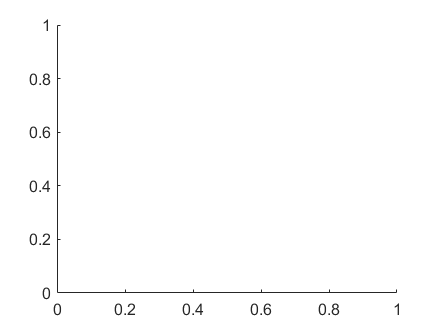

clear all

a = arduino;

% Initialize
joy = zeros(200,1);
joyBtn = zeros(200,1);
btn = zeros(200,1);
t = seconds(joy);
configurePin(a,'D2','DigitalInput')
configurePin(a,'D4','Pullup')
an = animatedline; % Initialize animated line

t0 = datetime('now');
for i = 1:200
    t(i) = datetime('now') - t0; % x-value
    joy(i) = readVoltage(a,'A1'); % y-value
%     plot(t(1:i),joy(1,i));
%     addpoints(an,t(i),joy(i));
    % drawnow limitrate;
    %(ii) = readDigitalPin(a,'D2');
    %btn(ii) = readDigitalPin(a,'D4');
end
plot(t(i:1),joy(i,1));

Error using plot
Vectors must be the same length.

addpoints(an,t(i),joy(i));
drawnow limitrate;
% httaps://www.mathworks.com/matlabcentral/answers/83192-plot-in-real-time
% figure(1);
% plot(t(1:i,,joy);
% figure(2);
% plot(t,joyBtn);
%figure(3);
%plot(t,btn);

% Joystick neutral is around 2.5
